## Définition du mouvement

% Vitesse du mobile
vmax = 0.5;  % m/s

% accélération du mobile
amax = 5; % m/s²

% Position initiale
x_i = 0; % mm
y_i = 0; % mm
theta_i = 0; % rad

% Position finale
x_f = 0; % mm
y_f = 200; % mm
theta_f = 0; % rad

distance = sqrt(x_f^2+y_f^2);
 

## Définition des constantes

% Hauteur mobile
% Largeur mobile
% Diamètre xx poulie ? Enrouleur ?
% Temps d'échantillonnage
dt = 0.001 ;

## Définition des lois en trapèze de vitesse

### Détermination du temps de chacune des phases

function [t1,t2,t3] = calcule_temps(amax, vmax, distance)
    % Pour une loi en trapèze de vitesse, on calcule :
    %    - t1, temps à partir duquel on est à vitesse constante ;
    %    - t2, temps à partir duquel on décélère ;
    %    - t3, temps à partir duquel on est à vitesse nulle.
    % Entrées :
    %  * amax : accélération en m²/s
    %  * vmax : vitesse en m/s
    %  * distance : distance à parcourir en mm
    
    distance = distance/1000 ;
    
    % Détermination du temps pour atteindre la vitesse max
    % vmax = t1*amax
    t1 = vmax/amax ;
    
    % On détermine la distance minimale pour réaliser un trapèze de vitesse (non demandé)
    dmin = t1*vmax;
    
    if distance > dmin  % On a un trapèze de vitesse
        t1 = vmax/amax;
        % Distance totale (aire sous le trapèze) L = ta*v + T*v
        % T : Temps à vitesse constante
        T = (distance - t1*vmax)/vmax;
        t2 = T+t1;
        t3 = t2+t1;
    else  % On a un triangle
        T = 0;
        % calcul de la vitesse atteinte va : L = ta*va et va = ta*a
        % On a L = ta*ta*a
        ta = sqrt(distance/amax);
        v = amax*ta;
        t1 = ta;
        t2 = t1;
        t3 = t1+t1;
    end
end

[t1,t2,t3] = calcule_temps(1,1,1)

t1 = 0.0316

t2 = 0.0316

t3 = 0.0632

### Détermination des lois de mouvements

% Détemination des profils de position, vitesse et accélération pour un déplacement donné
% Indépendant du RC4. 
function [les_t,les_x,les_v,les_a] = calcule_profil(amax,vmax,distance,dt)
    
    [t1,t2,t3] = calcule_temps(amax,vmax,distance);
    
    % On ajoute t1 au temps de simulation
    les_t = [];
    t = 0;
    while t < t3+t1 
        les_t(end+1) = t ;
        t = t+dt;
    end

    les_a = [];
    les_v = [];
    les_x = [];
    
    % Génération des profils
    for i = 1:length(les_t) 
        t = les_t(i);
        if t<t1 
            les_a(end+1) = amax;
            les_v(end+1) = amax*t;
            les_x(end+1) = 0.5*amax*t*t;
        elseif t<t2  
            les_a(end+1) = 0;
            les_v(end+1) = vmax;
            les_x(end+1) = les_x(end)+vmax*dt;
            
        elseif t<t3  
            les_a(end+1) = -amax;
            les_v(end+1) = les_v(end)-amax*dt;
            les_x(end+1) = les_x(end)+les_v(end)*dt;
        else 
            les_a(end+1) = 0;
            les_v(end+1) = 0;
            les_x(end+1) = les_x(end);
        end
    end
end

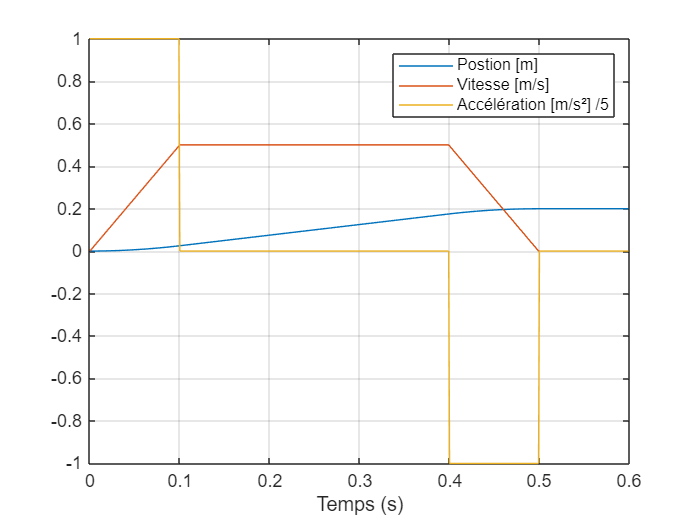

[les_t,les_x,les_v,les_a] = calcule_profil(amax,vmax,distance,dt);
plot(les_t,les_x,les_t,les_v,les_t,les_a/5 )
xlabel('Temps (s)');
grid on;
legend('Postion [m]', ...
    'Vitesse [m/s]', ...
    'Accélération [m/s²] /5')